## 异常值检测

异常值检测用于识别与其余数据显著不同的数据点。

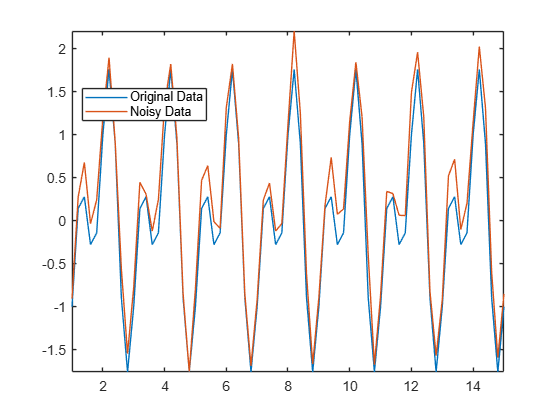

t = 1:0.2:15;
A = sin(2*pi*t) + cos(2*pi*0.5*t);
Anoise = A + 0.5*rand(1,length(t));
plot(t,A,t,Anoise)
axis tight
legend('Original Data','Noisy Data','location','best')

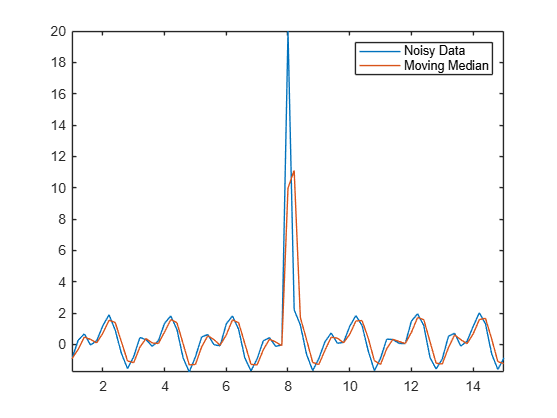


Anoise(36) = 20;
Amedian = smoothdata(Anoise,'movmedian');
plot(t,Anoise,t,Amedian)
axis tight
legend('Noisy Data','Moving Median')

稳健 Lowess 方法是另一种平滑方法，当数据中除了噪声之外还存在异常值时特别有用。

t = 1:0.2:15;
A = sin(2*pi*t) + cos(2*pi*0.5*t);
Anoise = A + 0.5*rand(1,length(t));
plot(t,A,t,Anoise)
axis tight
legend('Original Data','Noisy Data','location','best')

Anoise(36) = 20;
Arlowess = smoothdata(Anoise,'rlowess',5);
plot(t,Anoise,t,Arlowess)
axis tight
legend('Noisy Data','Robust Lowess')

使用 `filloutliers`函数并通过指定填充方法来替换数据中的异常值。

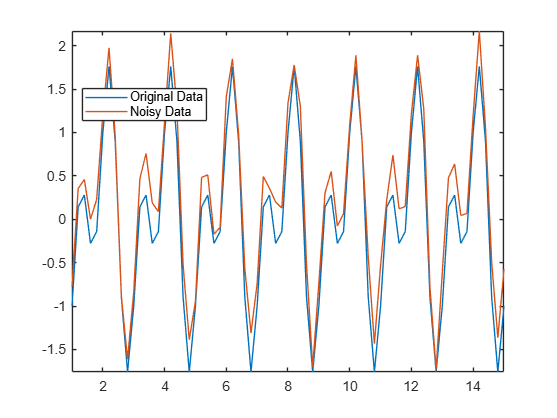

t = 1:0.2:15;
A = sin(2*pi*t) + cos(2*pi*0.5*t);
Anoise = A + 0.5*rand(1,length(t));
plot(t,A,t,Anoise)
axis tight
legend('Original Data','Noisy Data','location','best')


Anoise(36) = 20;
TF = isoutlier(Anoise);
ind = find(TF)

ind = 36

Aoutlier = Anoise(ind)

Aoutlier = 20

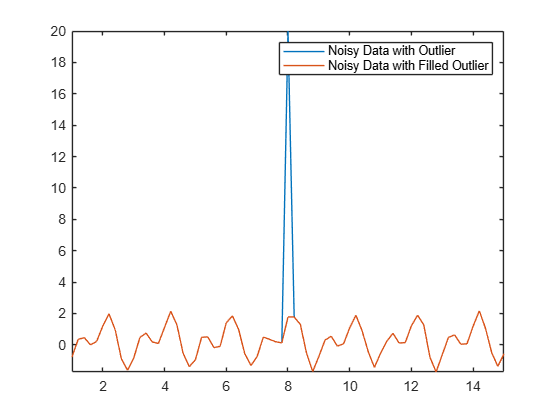

Afill = filloutliers(Anoise,'next');
plot(t,Anoise,t,Afill)
axis tight
legend('Noisy Data with Outlier','Noisy Data with Filled Outlier')